**The following are symbols in use**

s = tf('s');
syms z;

**The following are the constant varible which will be taken in use**

*See the rapport for how the where determined. Motor 1 (PAN)*

pan_K = 0.530516;   % Motorconstant (er lavet)
pan_La = 3.362;     % Inductance in mH (updated)
pan_Ra = 10.56;     % Resistance in ohm (updated)
pan_B = 0.000931;   % Motror frictions koefficient
pan_J = 0.0019;     % Motor intertimoment kg*m^2

*Motor 2 (TILT)*

tilt_K = 0.530516;  % Motorconstant (er lavet)
tilt_La = 3.3469;   % Inductance in mH (updated)
tilt_Ra = 8.060;    % Resistance in ohm (updated)
tilt_B = 0.000931;  % Motror frictions koefficient
tilt_J = 0.0019;    % Motor intertimoment kg*m^2

J_bcs= 0.0889; % Intertimoment for pan/tilt i best kg*m^2
J_wcs= 0.0946; % Intertimoment for pan/tilt i worst kg*m^2

**The following are the performance specifications**

*It is for the outer loop*

tr = 1;  % Rise time
Mp = 0.1;   % Overshoot
ts = 3;   % Settling time

*Below is in freqency domain*

wn = 1.8/tr;
zeta = sqrt(((log(Mp)/-pi)^2)/(1+(log(Mp)/-pi)^2));
sigma = 4.6/ts;

**The following is the three transfer functions**

*Keep in mind they are general expression. Needs to be specified for the motors accordingly.*

*Motor 1 (PAN)*

pan_TF_c =1/(pan_Ra + pan_La*s + ((pan_K*s)/(pan_J*s^2+pan_B*s))); %Current
pan_TF_v =pan_K/((pan_Ra + pan_La)*(pan_J*s+pan_B)+pan_K); %Velocity
pan_TF_p =1/s; %Position


*Motor 2 (TILT)*

tilt_TF_c =1/(tilt_Ra + tilt_La*s + ((tilt_K*s)/(tilt_J*s^2+tilt_B*s))); %Current
tilt_TF_v =tilt_K/((tilt_Ra + tilt_La)*(pan_J*s+tilt_B)+tilt_K)*tilt_Ra; %Velocity
tilt_TF_p =1/s; %Position

**The following is the begining of finding a suitable controller for the system**

Encoder =200 khz ::: ADC_current = 1 mhz  ::: ca 5 gange hurtigere

**Controllability**

*Uses all the constants*

%første tilgang til løsningen
%sysNum = [0 0 K]
%sysDen = [(Ra*J + La*J), (Ra*B + La*B + K) 0]
%sysFrac = tf(sysNum,sysDen) %Der er en afvigelse!
%[A,B,C,D] = tf2ss(sysNum,sysDen)
%controllability = ctrb(A,B)

%A = [0 (K/(J*(Ra+La))); 0 -((Ra*B+La*B+K)/J*(Ra+La))]
%B = [0; (K/(J*(Ra+La)))]
%controllability = ctrb(A,B)
%rank(controllability)

%%andne tilgang til løsningen med afvigelse
% s = tf('s')
% sysLigning = K/(Ra*J*s^2 + La*J*s^2 + Ra*B*s + La*B*s * K*s) %DET ER DET SAMME! (hvilket var meningen)
% sysLigning = tf(sysLigning) %DET ER DET SAMME! (hvilket var meningen)
% sysLigningNum = [0 0 K]
% sysLigningDenum = [0.02096 0.006344 0]
% [A,B,C,D] = tf2ss(sysLigningNum, sysLigningDenum)
%controllability = ctrb(A,B)

**Determining constants for the regulators**

Motor 1 (PAN)

[num_c_pan, den_c_pan] = tfdata(pan_TF_c, 'v'); %For Current
[num_p_pan, den_p_pan] = tfdata(pan_TF_p, 'v'); %For position
[num_v_pan, den_v_pan] = tfdata(pan_TF_v, 'v'); %For velocity

pan_TF_vv =pan_K/((pan_Ra + pan_La)*(pan_J*s+pan_B)+2*pan_K); %Velocity med spændingen som input
[num_vv_pan, den_vv_pan] = tfdata(pan_TF_v, 'v'); %Current

panTF = pan_TF_v*pan_TF_p;
[num_TF_pan, den_TF_pan] = tfdata(panTF, 'v');

%Performance specification


%controlSystemDesigner(panTF)
%pidTuner(panTF)
%RegulatorPan =  0.32133*(s+10.04)^2/s har ikke god nok bandwidth

%PID controller
%RegulatorPan=(307.73*(s+907.8)^2)/s

RegulatorPan=3.2733*(s+16.33)^2/s

RegulatorPan =
 
  3.273 s^2 + 106.9 s + 872.9
  ---------------------------
               s
 
Continuous-time transfer function.



[PID, info]=pidtune(RegulatorPan,'PID2')

PID =
 
      1 
  Ki ---
      s 

  with Ki = 0.163
 
Continuous-time 2-DOF I-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 17.4116
           PhaseMargin: 93.6719




Kp_pan = 2.536*10^8;
Ki_pan = 5.587*10^5;
Kd_pan = 307.7;

Ti_pan = Kp_pan/Ki_pan;
Tt_pan = 1;
Td_pan = Kd_pan/Kp_pan;

%LP filter
N_pan = 1000;


Motor 2 (TILT)

[num_c_tilt, den_c_tilt] = tfdata(tilt_TF_c, 'v') %For Current

num_c_tilt =          0    0.0019    0.0009         0


den_c_tilt =     0.0064    0.0184    0.5380         0


[num_p_tilt, den_p_tilt] = tfdata(tilt_TF_p, 'v') %For position

num_p_tilt =      0     1


den_p_tilt =      1     0


[num_v_tilt, den_v_tilt] = tfdata(tilt_TF_v, 'v') %For velocity

num_v_tilt =          0    4.2760


den_v_tilt =     0.0217    0.5411



tilt_TF_vv =tilt_K/((tilt_Ra + tilt_La)*(tilt_J*s+tilt_B)+2*tilt_K) %Velocity med spændingen som input

tilt_TF_vv =
 
       0.5305
  -----------------
  0.02167 s + 1.072
 
Continuous-time transfer function.



[num_vv, den_vv] = tfdata(tilt_TF_vv, 'v') %Current

num_vv =          0    0.5305


den_vv =     0.0217    1.0717



tiltTF = tilt_TF_v*tilt_TF_p

tiltTF =
 
          4.276
  ----------------------
  0.02167 s^2 + 0.5411 s
 
Continuous-time transfer function.




%Performance specification


%controlSystemDesigner(tiltTF)
%pidTuner(tiltTF)

%Constants here for P I D
RegulatorTilt=307.73*(s+907.8)^2/s % Dette er for

RegulatorTilt =
 
  307.7 s^2 + 5.587e05 s + 2.536e08
  ---------------------------------
                  s
 
Continuous-time transfer function.




Kp_tilt = 5.41;
Ki_tilt = 4.75;
Kd_tilt = 0.432;

%LP filter
N_tilt = 1000;


**Simulink Constants**

%Det som vi vil have ud her er de samlede transferfunktion. Altså hvor
%regulatoren er kombineret med for plant



**Bandwith of system**

%Checks the bandwidth of the system

Closed_loop_pan = RegulatorPan*panTF/(1+RegulatorPan*panTF);
Closed_loop_tilt = RegulatorTilt*tiltTF/(1+RegulatorTilt*tiltTF)

Closed_loop_tilt =
 
          28.52 s^5 + 5.249e04 s^4 + 2.479e07 s^3 + 5.868e08 s^2
  ----------------------------------------------------------------------
  0.0004697 s^6 + 28.54 s^5 + 5.249e04 s^4 + 2.479e07 s^3 + 5.868e08 s^2
 
Continuous-time transfer function.




BoS_pan = bandwidth(Closed_loop_pan)

BoS_pan = 77.2662

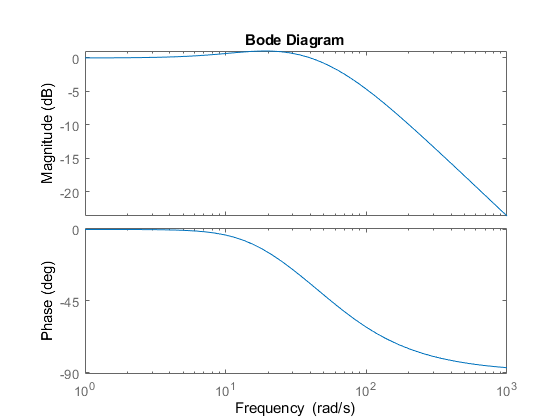


bode_pan =

	resppack.bodeplot



bode_pan = bodeplot(Closed_loop_pan)


BoS_tilt = bandwidth(Closed_loop_tilt)

BoS_tilt = 6.2351e+04

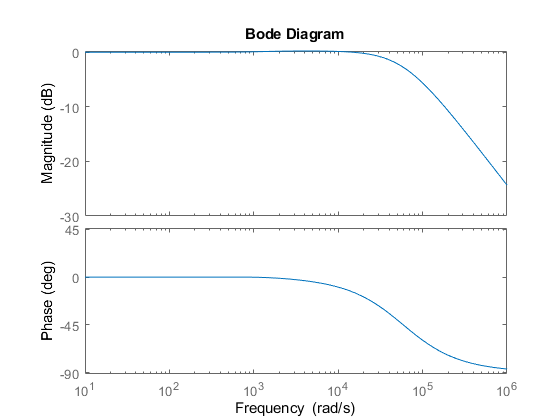


bode_tilt =

	resppack.bodeplot



bode_tilt =bodeplot(Closed_loop_tilt)

**Difference Eqautions**

clear s;
syms s

PanCon =3.2733*(s+16.33)^2/s

$$PanCon = \frac{32733\,{\left(s+\frac{1633}{100}\right)}^{2}}{10000\,s}$$



PanSys_z = c2d(panTF,0.1) %sample time Ts =0.1s

PanSys_z =
 
   0.05619 z + 0.02891
  ----------------------
  z^2 - 1.128 z + 0.1281
 
Sample time: 0.1 seconds
Discrete-time transfer function.



TiltSys_z = c2d(tiltTF,0.1) %sample time Ts =0.1s

TiltSys_z =
 
     0.4998 z + 0.2253
  -----------------------
  z^2 - 1.082 z + 0.08235
 
Sample time: 0.1 seconds
Discrete-time transfer function.




PanCon_z =ztrans(PanCon)

$$PanCon\_z = \frac{53452989\,z}{500000\,\left(z-1\right)}+\frac{32733\,z}{10000\,{\left(z-1\right)}^{2}}+\frac{87288731037\,\mathrm{ztrans}\left(\frac{1}{s},s,z\right)}{100000000}$$

PanCon_iz =iztrans(PanCon)

$$PanCon\_iz = \frac{87288731037\,\delta_{n-1,0}}{100000000}+\frac{53452989\,\delta_{n,0}}{500000}+\frac{32733\,\mathrm{iztrans}\left(s,s,n\right)}{10000}$$


Pan =0.5305/0.02645*s^2+0.5435*s

$$Pan = \frac{10610\,s^{2}}{529}+\frac{1087\,s}{2000}$$

df = ilaplace(Pan)

$$df = \frac{1087\,\delta^{\prime }(t)}{2000}+\frac{10610\,\delta^{\prime \prime }(t)}{529}$$




%PanSys_z = ztrans(RegulatorPan*panTF)


%DE_CON_Pan = iztrans(PanSys_z)
%DE_CON_Tilt = iztrans(RegulatorPan3)


%være disse difference equations som skal implementeres på tiva boardet